%利用buttord设计IIR低通滤波器
rp=0.5;rs=60;   %通带波纹系数rp，最小阻带衰减rs
Ft=7000;
Fp=320;
Fs=2000;                                       
wp=2*pi*Fp/Ft;
ws=2*pi*Fs/Ft;            %求出待设计的模拟滤波器的边界频率
[n,wn]=buttord(wp,ws,rp,rs,'s') %低通滤波器的阶数和截止频率

n = 5

wn = 0.4509

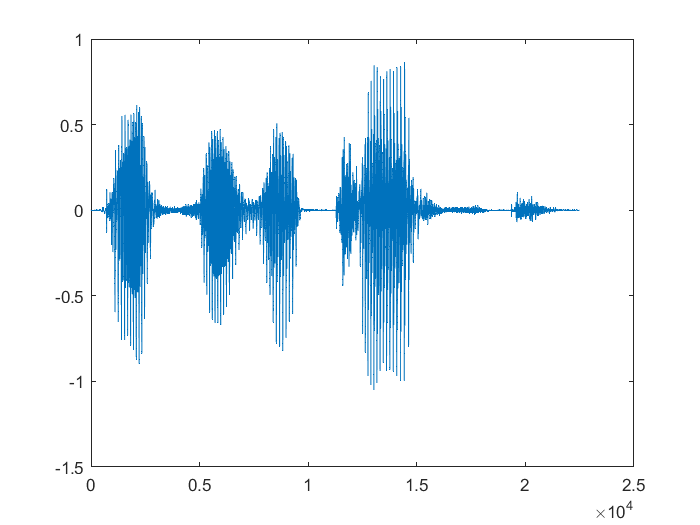

[b,a]=butter(n,wn,'s');         %滤波器的传输函数
[bz,az]=bilinear(b,a,0.5);


fs=16000;
y=audioread('test_16k.wav');
f=filter(bz,az,y);    %滤波
plot(f)

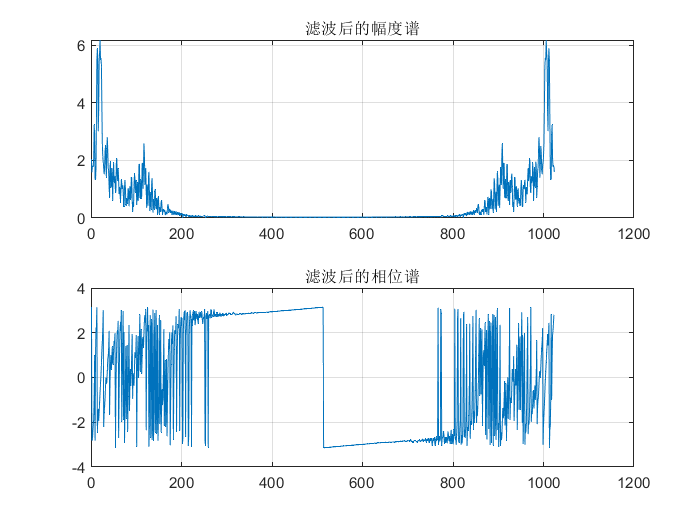

f1=fft(f,1024);
subplot(2,1,1)
plot(abs(f1));  
title('滤波后的幅度谱');
grid;
subplot(2,1,2)
plot(angle(f1));    
title('滤波后的相位谱');
grid;

audiowrite('audio4.wav',f,fs);

%对滤波后的声音进行储存。

